# スターリングの公式について

## 目的

**階乗を指数関数によって近似的に評価**するために、統計力学では以下の Stirling の公式がよく用いられる

$N \gg 1$のとき、

    (1) $\ln N! \approx N \ln N - N +\frac{1}{2} \ln \left( 2\pi N \right)$

または、より粗い近似として、

    (2) $\ln N! \approx N \ln N - N$

## グラフを描いて確認する

Q.1

- (a) $\ln N!$

- (b) $N \ln N - N +\frac{1}{2} \ln \left( 2\pi N \right)$

- (c) $N \ln N - N$ 

を$N$の関数としてグラフで表せ。

→ ３つの曲線がほぼ一致しているように見える。

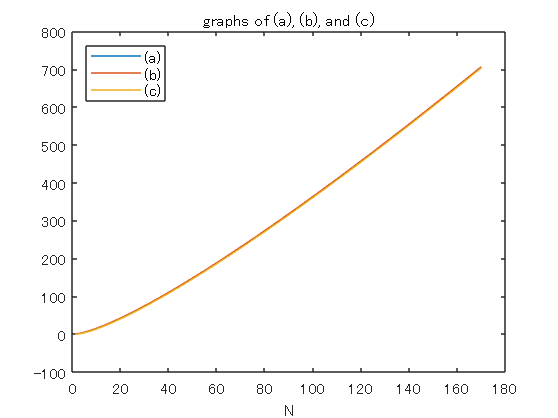

format long
n0 = 1;
n1 = 170;
x = linspace(1,n1,n1);
y1 = log(factorial(x));
y2 = x .* log(x) - x + 0.5 * log(2*pi*x);
y3 = x .* log(x) - x;

plot(x,y1)
hold on 
plot(x,y2)
plot(x,y3)
legend('(a)','(b)','(c)', "Location",'northwest');
title('graphs of (a), (b), and (c)')
xlabel('N');
hold off

format

Q2. Q1. において、 $N$の範囲を例えば、 $50\leq N \leq 60$に限定してグラフを描け。

→ (c)の誤差が顕著になる。(a)と(b)は一致しているように見える。

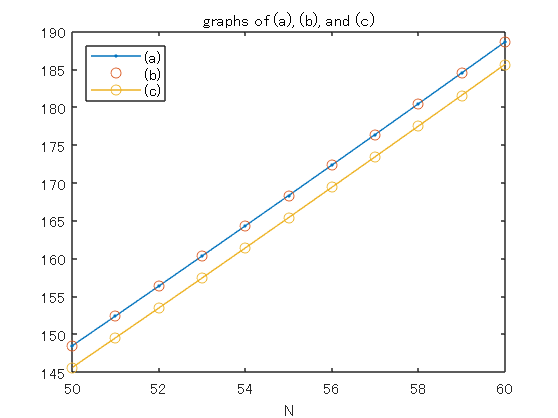

plot(x,y1, '.-')
hold on 
plot(x,y2,'o')
plot(x,y3,'-o')
legend('(a)','(b)','(c)', "Location",'northwest');
title('graphs of (a), (b), and (c)')
xlabel('N');
xlim([50 60]);
hold off

## 近似式(1), (2)との相対誤差をグラフで表す

厳密な式を $f(x)$、近似式を $g(x)$とすれば、相対誤差 $r$ は次式のように与えられる。


$$r = \left| \frac{f(x)-g(x)}{f(x)} \right|$$


Q3. Q1の(a)と(b)との相対誤差、(a)と(c)との相対誤差を求め、グラフで表せ。

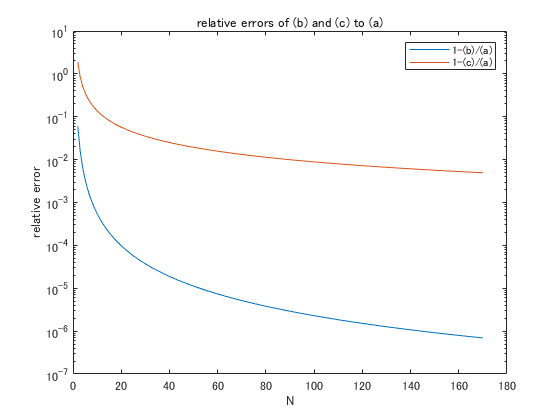

semilogy(x,1-y2./y1)
hold on 
semilogy(x,1-y3./y1)
legend('1-(b)/(a)','1-(c)/(a)', "Location",'northeast');
title('relative errors of (b) and (c) to (a)')
xlabel('N');
ylabel('relative error');
hold off

## 近似式(2)の証明

近似式(2)については、 $\ln x$の積分と和に着目することによって近似的に証明できる。


$$\ln \;N=\sum_{\textrm{ｊ＝１}}^N \ln \;j\;\approx \int_1^N \ln \;x\;\textrm{dx}={\left\lbrack x\;\ln \;x-x\right\rbrack }_1^N =N\;\ln \;N-N+1\approx N\;\ln \;N-N$$


この証明をグラフで表すとこのようになる。

（スライドバーによって$x_{1}$の値を変えることができる。）

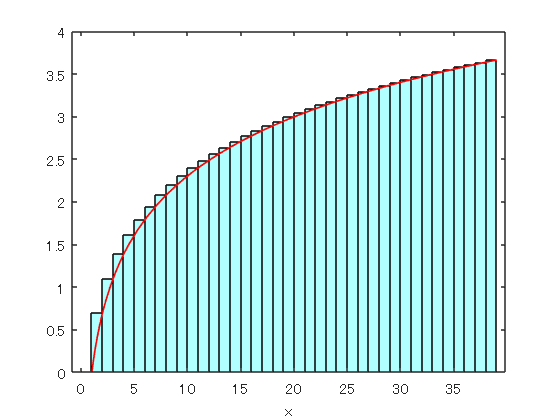


x1 =39;
xl1 = linspace(1,x1,x1);
yl1 = log(xl1);
bar(xl1-0.5, yl1, 1, "cyan", 'FaceAlpha',.3)
hold on
xlabel("x")
fplot(@(x)log(x), [1, x1], 'LineWidth',1,"Color",'r')
hold off

## 演習

Q4. $N=10$ および $N=1000$ のそれぞれの場合において、 Q1 の(a)と(b)の相対誤差、ならびに、(a)と(c)の相対誤差を求めよ。

## 参考文献